addpath 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;startup;yalmip('clear');close all

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


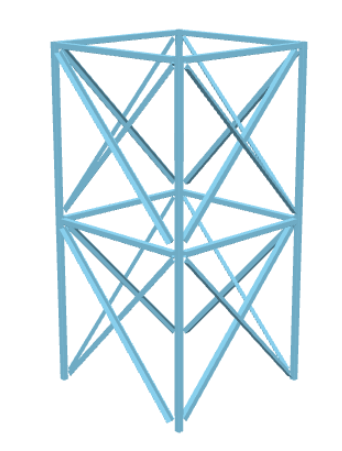

width = 2.9;
length = 2.9;
height = 3;
topHeight = 20;
nbricks = 7;

import = importdata("sectionsSetRHS.mat");
nRhs = numel(table2array(import(:,"A")));
crossSectionsSet.A = zeros(nRhs*2,1);
crossSectionsSet.A(1:nRhs) = cat(1, table2array(import(:,"A")));
crossSectionsSet.A(nRhs+1:nRhs*2) = table2array(import(:,"I_y")) .* 24/length^2;

crossSectionsSet.I = zeros(nRhs*2,1);
crossSectionsSet.I(1:nRhs) = cat(1, table2array(import(:,"I_y")));
crossSectionsSet.I(nRhs+1:nRhs*2) = 1;

na = numel(crossSectionsSet.A); 


## Ground structure

### Nodes

nodes.x = [[0;length;length;0];kron(ones(nbricks,1),[length/2;length;length/2;0;0;length;length;0])];                            % x coordinates of nodes
nodes.y = [[0;0;width;width];kron(ones(nbricks,1),[0;width/2;width;width/2;0;0;width;width])];                              % y coordinates of nodes
nodes.z = [0;0;0;0];
for i = 1:nbricks
    nodes.z  = [nodes.z; [height/2;height/2;height/2;height/2;height;height;height;height] + (i-1) .* [height;height;height;height;height;height;height;height]];
end
nodes.z((nbricks)*7+4:(nbricks+1)*7+4) =[topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight-(topHeight - height*(nbricks-1))/2;topHeight;topHeight;topHeight;topHeight]; % z coordinates of nodes
nnodes = numel(nodes.x); 

### Elements

elements.modulNodes1 = [1;2;3;4; 1;2;2;3;3;4;4;1; 9;10;11;12;  9;10];   % elements starting nodes   
elements.nodes1 = (reshape(kron(elements.modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(elements.modulNodes1))*8);
elements.modulNodes2 = [9;10;11;12; 10;9;11;10;12;11;9;12; 10;11;12;9;  11;12];   % elements ending nodes
elements.nodes2 = (reshape(kron(elements.modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(elements.modulNodes2))*8);
nr = numel(elements.nodes1);  % number of elements  

### Groups of elements

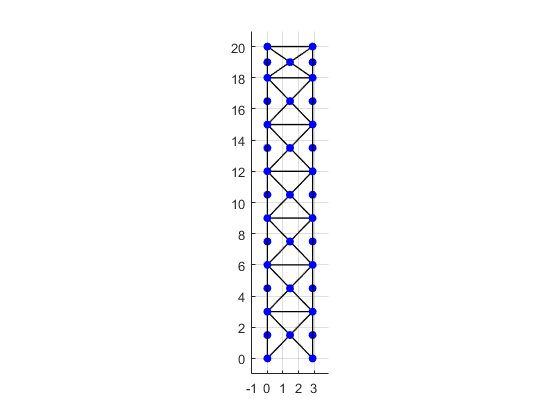

modulElemGroup = [1;1;1;1; 3;3;3;3;3;3;3;3;    2;2;2;2;  4;4];
elemGroup = reshape(kron(modulElemGroup', ones(nbricks, 1))', 1, [])';
ng = max(max(elemGroup));

plot3([nodes.x(elements.nodes1) nodes.x(elements.nodes2)]', ...
     [nodes.y(elements.nodes1) nodes.y(elements.nodes2)]', ...
     [nodes.z(elements.nodes1) nodes.z(elements.nodes2)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'blue', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
view([90 0])
hold off;

### Material and cross-section

elements.E = 210*10^9 ;    % Young moduli of individual elements
elements.Rho = 7850;    

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [1;2;3;4];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;2;3;4];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];          % node indices with restricted z-direction displacements

### Load

loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*8).',1,[])';             % node indices with x-direction forces
loads.y.value = ones(nbricks*2,1)*0.25;             % magnitude of the x-direction forces
loads.x.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.x.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 
loads.z.nodes = [1;2;3;4]+(nbricks)*8;             % node indices with y-direction forces
loads.z.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
dofs = reshape(dofs.',[],1);
nd = sum(dofs,"all");

## Optimization parameters

maximumDisplacement = 0.04;
minimumDisplacement = -0.04;
yieldStrength = 235*10^6 ;
maximumStress   = zeros(nr/nbricks,1);
Lcrit = ones(nr/nbricks,1);
for i=1:max(size(modulElemGroup))
    if modulElemGroup(i) == 4
        maximumStress(i)   = 1*10^12;
%         Lcrit(i) = 1;
    else
        if modulElemGroup(i) == 3
            maximumStress(i)   = yieldStrength;
%             Lcrit(i) = 0.5;
        else
            maximumStress(i)   = yieldStrength;    
%             Lcrit(i) = 1;
        end
    end
end
maximumStress = kron(ones(nbricks,1),maximumStress);
Lcrit = kron(ones(nbricks,1),Lcrit);

### Design variables

% x = binvar(ng*na,1);
x1 = binvar(na,1);
x1(nRhs+1:na) = 0;
x2 = binvar(na,1);
x2(nRhs+1:na) = 0;
x3 = binvar(na,1);
x3(nRhs+1:na) = 0;
x4(nRhs+1:na) = x2(1:nRhs);
x = double2sdpvar(zeros(na*ng,1));
x(1:na,1) = x1;
x(1+na:na*2,1) = x2;
x(1+2*na:3*na,1) = x3;
x(1+3*na:4*na,1) = x4;
s = sdpvar(nr*na,1);
u = sdpvar(nd,1);    

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [deltaX./lengths deltaY./lengths deltaZ./lengths];
codeNumbers = [repmat(elements.nodes1,1,3) repmat(elements.nodes2,1,3)]*3-2 + repmat([0 1 2 0 1 2], nr, 1);
staticMatrix = sparse(codeNumbers(:), ...
                      repmat(1:nr,1,6), ...
                      [-cosinus(:,1); -cosinus(:,2); -cosinus(:,3); cosinus(:,1); cosinus(:,2); cosinus(:,3);], ...
                      nnodes*3, nr);
matrixB = full (staticMatrix(dofs,:) );

## Optimization problem formulation and solution

Fmax =  diag ( kron( ones( nr,1).*maximumStress , crossSectionsSet.A) );
Fmin = -diag(kron( ones(nr,1) .* (elements.E*pi^2*((lengths.*Lcrit).^-2)) , crossSectionsSet.I));
cmin = reshape((kron(elements.E*crossSectionsSet.A', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* minimumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* maximumDisplacement)'))', 1, []);
Cmin = diag(cmin);
cmax = reshape((kron(elements.E*crossSectionsSet.A', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* maximumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* minimumDisplacement)'))', 1, []);
Cmax = diag(cmax);
I = eye(nr * na);
B = kron(matrixB, ones(1, na));
K = kron ( kron ((elements.E./lengths), crossSectionsSet.A), ones(nd,1)') .* B';

Q = sparse(1:nr,elemGroup,1,nr,ng);
G = kron( Q, eye(na));
forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
f = forceVector(reshape(dofs.', 1, [])');
IM = zeros(nr, na * nr);
for j = 1:nr
        IM(j, na*(j-1)+1:na*(j)) = 1;
end

### Constraints

y = double2sdpvar(zeros(2*na*nr+ nd,1));
y(1:nr*na,1) = G*x;
y(1+nr*na:nr*na+nd,1) = u;
y(1+nr*na+nd:2*nr*na+nd,1) = s;

#### Constraint 1: Inequality


$$A_{ineq} y \leq b
$$


**Matrix **$A_{ineq}
$

Aineq = zeros(4*na*nr,2*nr*na+nd);

*First collumn*

Aineq(1:nr*na,1:nr*na)              =  Fmin;
Aineq(1+nr*na:2*nr*na,1:nr*na)      = -Fmax;
Aineq(1+2*nr*na:3*nr*na,1:nr*na)    = -Cmin;
Aineq(1+3*nr*na:4*nr*na,1:nr*na)    =  Cmax;

*Second collumn*

Aineq(1+2*nr*na:3*nr*na,1+nr*na:nr*na+nd)    =  K;
Aineq(1+3*nr*na:4*nr*na,1+nr*na:nr*na+nd)    = -K;

*Third collumn*

Aineq(1:nr*na,1+nr*na+nd:2*nr*na+nd)              = -I;
Aineq(1+nr*na:2*nr*na,1+nr*na+nd:2*nr*na+nd)      =  I;
Aineq(1+2*nr*na:3*nr*na,1+nr*na+nd:2*nr*na+nd)    =  I;
Aineq(1+3*nr*na:4*nr*na,1+nr*na+nd:2*nr*na+nd)    = -I;

**Vector **$b
$

b = zeros(4*na*nr,1);
b(1+2*nr*na:3*nr*na,1) = -diag(Cmin);
b(1+3*nr*na:4*nr*na,1) =  diag(Cmax);
constIneq = [Aineq * y <= b]:'Nerovnost';

#### Constraint 2: Equality


$$A_{eq} y = b_{eq}
$$


**Matrix **$A_{eq}
$

Aeq = zeros(nd + nr,2*nr*na+nd);
Aeq(nd+1:nd+nr,1:nr*na) = IM;
Aeq(1:nd,nr*na+nd+1:nr*na+nd+nr*na) = B;


**Vector **$b_{eq}$

beq = zeros(nd + nr,1);
beq(1:nd,1) = f;
beq(nd+1:nd+nr,1) = ones(nr,1);
constEq = [Aeq * y == beq]:'Rovnost';

#### Constraint 3: Box constraints

***Lower bound***

lb = zeros(nr*na*2+nd,1);
lb(1:nr*na) = 0;
lb(nr*na+1:nr*na + nd) = minimumDisplacement;
lb(nr*na+nd+1:nr*na*2+nd) = -kron( ones(nr,1) .* (elements.E*pi^2*((lengths.*Lcrit).^-2)) , crossSectionsSet.I);


**Upper bound**

ub = zeros(nr*na*2+nd,1);
ub(1:nr*na) = 1;
ub(nr*na+1:nr*na + nd) = maximumDisplacement;
ub(nr*na+nd+1:nr*na*2+nd) = kron(maximumStress,crossSectionsSet.A);

***Box constraint***

constBox = [(lb <= y)]:'Dolní mez' & [(y <= ub)]:'Horní mez';

### Objective function

m = elements.Rho * kron(lengths,ones(na,1))' .* kron(ones(nr,1),crossSectionsSet.A)';
M = sparse(1,nr*na*2 + nd);
M(1:nr*na) = m;
objective = M * y;

### Solution

ops = sdpsettings('solver', 'gurobi', 'gurobi.Method', 2);  % Nastavení Gurobi solveru s metodou BnB
ops = sdpsettings(ops,'verbose',1,'debug',1);
constraints = [constIneq, constEq, constBox];  % Kombinace všech omezení
result = optimize(constraints, objective, ops);

Set parameter Username
Set parameter Method to value 2
Set parameter NodefileDir to value ""
Academic license - for non-commercial use only - expires 2024-11-07
Gurobi Optimizer version 10.0.3 build v10.0.3rc0 (win64)

CPU model: Intel(R) Core(TM) i5-8300H CPU @ 2.30GHz, instruction set [SSE2|AVX|AVX2]
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads

Optimize a model with 16506 rows, 2463 columns and 41970 nonzeros
Model fingerprint: 0xd42053dd
Variable types: 2436 continuous, 27 integer (27 binary)
Coefficient statistics:
  Matrix range     [6e-01, 1e+11]
  Objective range  [1e+02, 4e+03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [4e-02, 5e+11]
         Consider reformulating model or setting NumericFocus parameter
         to avoid numerical issues.
Presolve removed 11883 rows and 1218 columns
Presolve time: 0.08s
Presolved: 4623 rows, 1245 columns, 23815 nonzero

check(constraints)

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|         Tag|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Elementwise inequality|       -7.4843e-07|             NaN|   Nerovnost|
|   #2|      Equality constraint|        -7.649e-11|             NaN|     Rovnost|
|   #3|   Elementwise inequality|                 0|             NaN|   Dolní mez|
|   #4|   Elementwise inequality|                 0|             NaN|   Horní mez|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.              |
| In practice, many solvers converge to slightly infeasible                      |
| solutions, which may cause some residuals to be negative.                      |
| It is up to the user to judge the importance and impact of                     |
| 

vectorX = (value(x)).* repmat(1:na, 1, ng)';
vectorX(value(x)==1) 

ans =      8
     2
     3
    11


## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(objective));

Optimized objective: 2013.757223


volume = sum(reshape(G*value(x), na, nr)'*crossSectionsSet.A.*lengths)

volume = 0.2565

vector = (G*value(x))

vector =      0
     0
     0
     0
     0
     0
     0
     1
     0
     0


    
vectorX = (value(x)).* repmat(1:na, 1, ng)';
vectorX(value(x)==1)    

ans =      8
     2
     3
    11


vectorS = (G*value(x)) .* value(s);
vectorS(G*value(x)==1);


### Plotting

Plot the optimal design. Note that the dimensions are scaled.

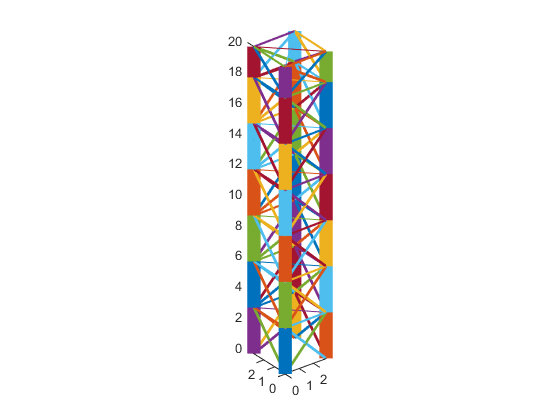

crossSections = reshape(vector, na, nr)'*crossSectionsSet.A;
nonzeroAreas = value(crossSections)>0;
p = plot3([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]',...
          [nodes.z(elements.nodes1(nonzeroAreas)) nodes.z(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal

## Basic FEM

% crossSections = reshape(G*value(x), na, nr)'*crossSectionsSet.A

% staticMatrix(dofs,:)*diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';

% stiffnessMatrix= staticMatrix(dofs,:)* diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% displacements = sum(abs(stiffnessMatrix\f) > 0.1)
% y = zeros(ng*na + na*nr+ nd,1);
% y(1:ng*na,1) = x;
% y(1+ng*na:ng*na+nd,1) = displacements;
% y(1+ng*na+nd:ng*na + nr*na+nd,1) = s;
% koo = (Aineq * y <= b)'
